# Multitask toxicity prediction using graph convolutional neural networks 

### Introduction

Unlike texts in natural language processing (NLP), nodes in a graph do not have any canonical positional information. It has been shown that Laplacian eigenvectors can be used as node positional encoding [1]. This simple example demonstrates how [Python-MATLAB](https://www.mathworks.com/help/matlab/call-python-libraries.html) can work together to process a [SMILES](https://en.wikipedia.org/wiki/Simplified_molecular-input_line-entry_system) database and generates positional encodings (PE) as part of graph-based transformer neural networks [2].  

### Setting up the conda environment and MATLAB workspace

This example uses some of the fucntions from [RDKit](https://www.rdkit.org/). We, therefore set the conda environment using these two lines. Make sure you give your python addess in the first line of "Setup_Conda_Environment.m" pyExec = '...\anaconda3\';

% Setup_Conda_Environment;
% !conda activate DeepChem-env

As a general task, let's first clear up the workspace.

clear;
clc;
close all;

### Read tox21.csv data into MATLAB and convert to molecular graphs

We can import data from .csv file as a matrix into MATLAB and visualize. Determine if you want to work form a csv file or the graph matrix is available. For this example, the data is already processed and stored in the "tox21_Graph_Data" folder.

doDataProccess = "false";

% if doDataProccess == ture

% The csv files are in "tox21_csv_Data". 
% The original "tox21.csv is too big to process. So we break it down to 8 files."

%   for S = 0:7
%          filename = ['tox21','_',num2str(S),'.csv']
%          [SMILES_Data,NR_SR] = ImportTox21(filename);
%          Graph_from_SMILES_Dataset(SMILES_Data,NR_SR,S);
%   end

% end

### Load data files

The following function uses RDKit to construct the molecular graph for the given SMILES structure. See the examples on [this page](https://www.rdkit.org/docs/GettingStartedInPython.html) to get started with the RDKit in Python. The adjacency and node matrices are stored in "graph_data.mat". 

GraphDataFolder = 'tox21_Graph_Data';
[Adjacency,Features,Labels] = Concatenate_Data(GraphDataFolder);

size(Adjacency) is [250   250  7831]
size(Features) is [250     7  7831]
size(Labels) is [1  7831]
Total number of toxic molecules is [2872]
Total number of nontoxic molecules is [4959]


### Prepare Data for Training

Partition the data into training, validation, and test partitions. We also do some pre-processing and normalization on the data before training. The details are explained at [MATLAB-GCN](https://www.mathworks.com/help/deeplearning/ug/node-classification-using-graph-convolutional-network.html). 

TrainPart = 0.8;
ValidPart = 0.1;
TestPart = 0.1;
Partitions= [TrainPart,ValidPart,TestPart];
[Adjacency,Features,Labels,classes,numOutputFeatures,numAtoms] = Partition_and_Prepare(Adjacency,Features,Labels,Partitions);

-------------Size FeaturesIn ------------


ans =          250           7        7831


### Training

Choose if you want to retain the network or use the pretrained parameters.

doTraining = true;

Specify training options and parameters:

numHiddenFeatureMaps = 64;
numEpochs = 50;  % Tried upto 1500
learnRate = 0.01;
validationFrequency = 10; % Tried up to 300
plots = "training-progress";
executionEnvironment = "cpu";
Params=[numHiddenFeatureMaps,numEpochs,learnRate,validationFrequency];
options = [plots,executionEnvironment];

-------- featureTrain ------------


ans =        86650           7


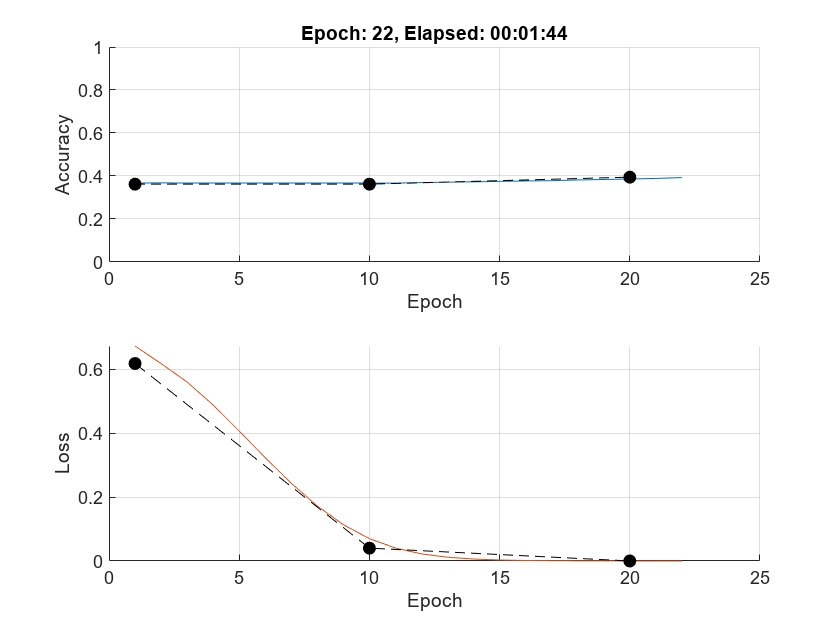

if doTraining == true
  [parameters] = Train_GCN(Adjacency, Features, Labels,Params,options,numOutputFeatures,classes,numAtoms);
else
  load trained_parameters.mat
end


save('parameters_final.mat','parameters')


### Testing

Test the model using the test data. Preprocess the test data using the same steps as for the training and validation data.

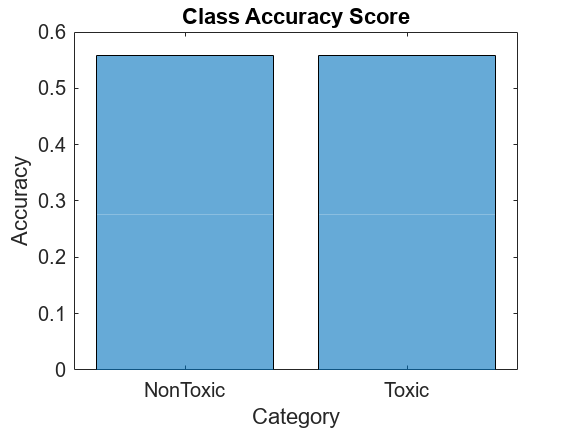

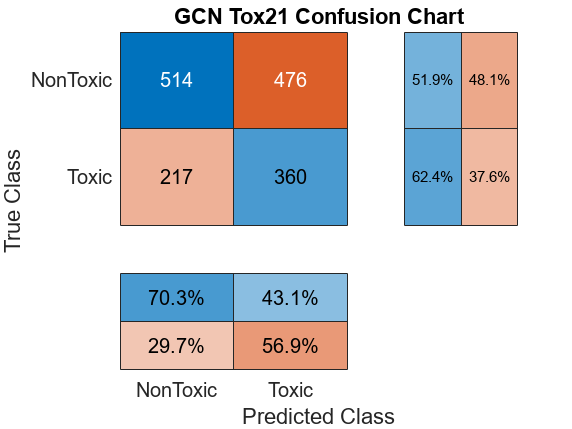

Test_GCN(Adjacency, Features, Labels,Params,options,numOutputFeatures,classes,numAtoms,parameters);

### Conclusion

### References

[1] Mikhail Belkin and Partha Niyogi. Laplacian eigenmaps for dimensionality reduction and data representation. [Neural computation, 15(6):1373–1396, 2003](https://direct.mit.edu/neco/article-abstract/15/6/1373/6730/Laplacian-Eigenmaps-for-Dimensionality-Reduction?redirectedFrom=fulltext).

[2] Chengxuan Ying, et. al., Do Transformers Really Perform Bad for Graph Representation?, [2106.05234.pdf (arxiv.org)](https://arxiv.org/pdf/2106.05234.pdf).

[3] Grégoire Mialon, et.al., GraphiT: Encoding Graph Structure in Transformers, [2106.05667.pdf (arxiv.org)](https://arxiv.org/pdf/2106.05667.pdf).